# Examnen primer parcial Robótica

Barajas Gaete Rodrigo Ainar

#### Introducción

   La robótica es una disciplina del área de la mecatrónica que combina diferentes conocimientos, ya sean de tipo electrónico, mecánico o computacional, con el fin de desarrollar sistemas mecatrónicos que sean capaces de realizar tareas autónomas o asistidas. Hoy en día, la robótica está presente en la mayoría de los sectores industriales, especialmente en el ámbito de producción, así como también es posible encontrarla en actividades cotidianas. Por estas y más razones, la robótica se ha vuelto indiscutiblemente un foco de interés para la investigación y el avance tecnológico.Uno de los principales efectos del gran interés por el tema es la generación y búsqueda de conocimiento (modelos, propuestas, diseños, etc.). Por ello, es necesario que, como futuros profesionistas, aprendamos a realizar un correcto análisis y comprensión de la rama teórica del tópico. 

Para este examen se buscara analizar y comprender el modelo propuesto, un robot tipo SCARA* (Selective Compliance Articulated Robot Arm*)*. *Estos robots se caracterizan por sus rápidos ciclos de trabajo, excelente repetitividad, gran capacidad de carga y su amplio campo de aplicación. 

Se obtendrán los modelos cinemáticos directos e inversos de: postura, velocidad y aceleración, a tráves del uso de conocimiento matemático y del software, con el objetivo de entender e interpretar el comportamiento del modelo propuesto. De igual forma se obtendrá el modelo dinámico directo e inverso, donde será necesario  obtener modelos como: Velocidades angulares, lineales, ecuacones de Lagrange, etc.

Definición de funciones

%Deficición de la función de manera simbolica
syms Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j)

%Definición de la transformación homógenea general

$$omega\_1\_1 = \omega_{1,1}$$

Tij(x_i_j,y_i_j,z_i_j,gi_j,bi_j,ai_j) = [cos(ai_j)*cos(bi_j) cos(ai_j)*sin(bi_j)*sin(gi_j)-sin(ai_j)*cos(gi_j) sin(ai_j)*sin(gi_j)+cos(ai_j)*sin(bi_j)*cos(gi_j) x_i_j; sin(ai_j)*cos(bi_j) cos(ai_j)*cos(gi_j)+sin(ai_j)*sin(bi_j)*sin(gi_j) sin(ai_j)*sin(bi_j)*cos(gi_j)-cos(ai_j)*sin(gi_j) y_i_j; -sin(bi_j) cos(bi_j)*sin(gi_j) cos(bi_j)*cos(gi_j) z_i_j; 0 0 0 1]

## Modelado del robot Scara

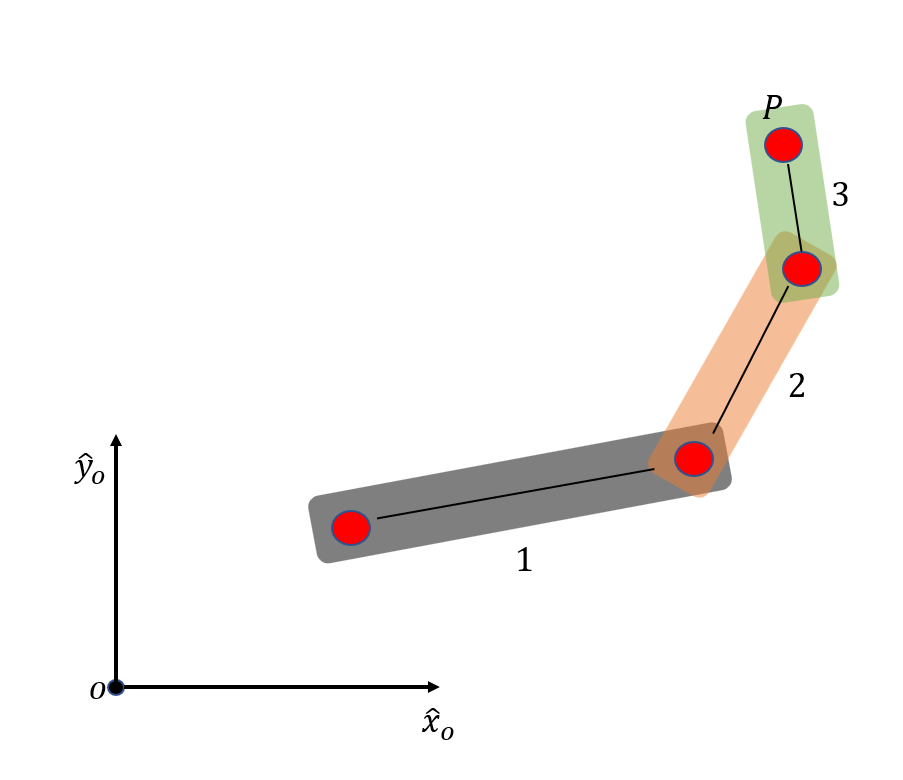

### Planteamiento del modelo cinemático de la posición

Partiendo de:


$${}^0\mathbf{T}_{P} ={}^0\mathbf{T}_{1}{}^1\mathbf{T}_{2}{}^0\mathbf{T}_{3}{}^3\mathbf{T}_{P} =\pmatrix{{}^0\mathbf{R}_P & {}^0\mathbf{p}_P \cr \mathbf{0}^T & 1  }$$


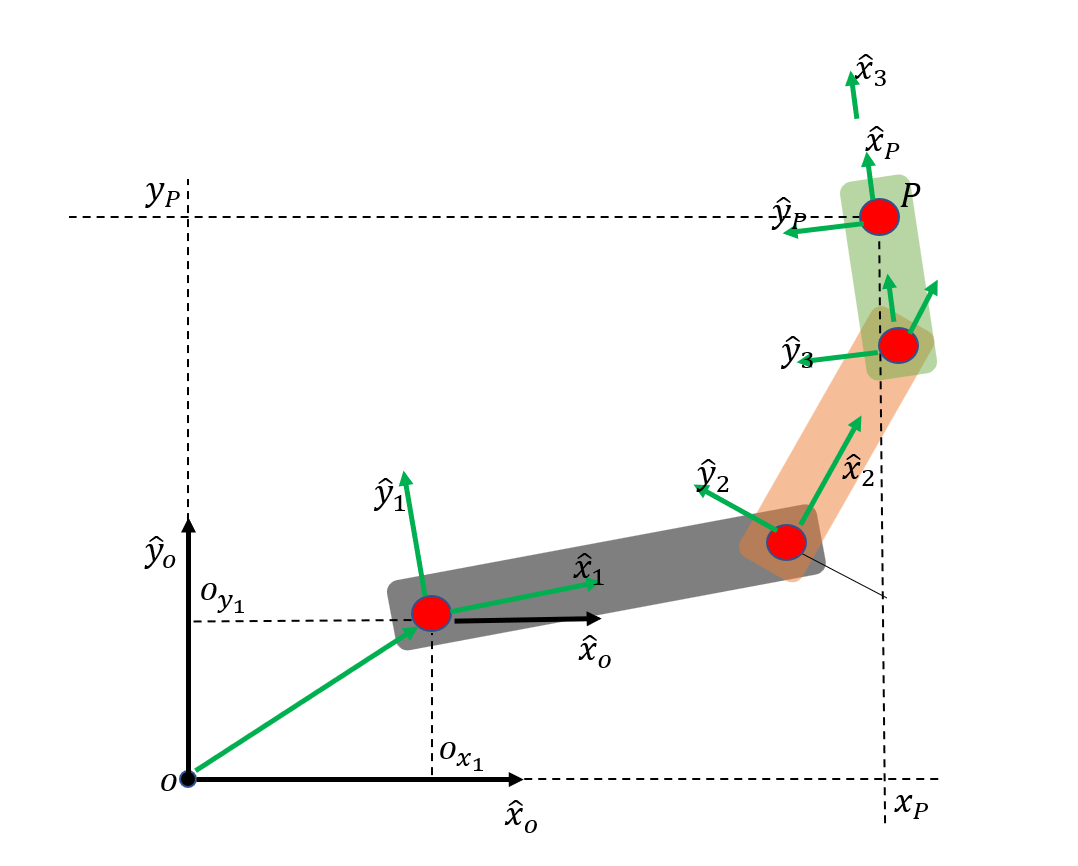

Donde 

- ${}^0\mathbf{T}_{1}$  :

syms x_O_1 y_O_1 theta_O_1 L_2 theta_1_2 L_3 theta_2_3 L_1

omega_O_O =      0
     0
     0



T_O_1 = Tij(x_O_1,y_O_1,0,0,0,theta_O_1)

n_1_1 =      0
     0
     1


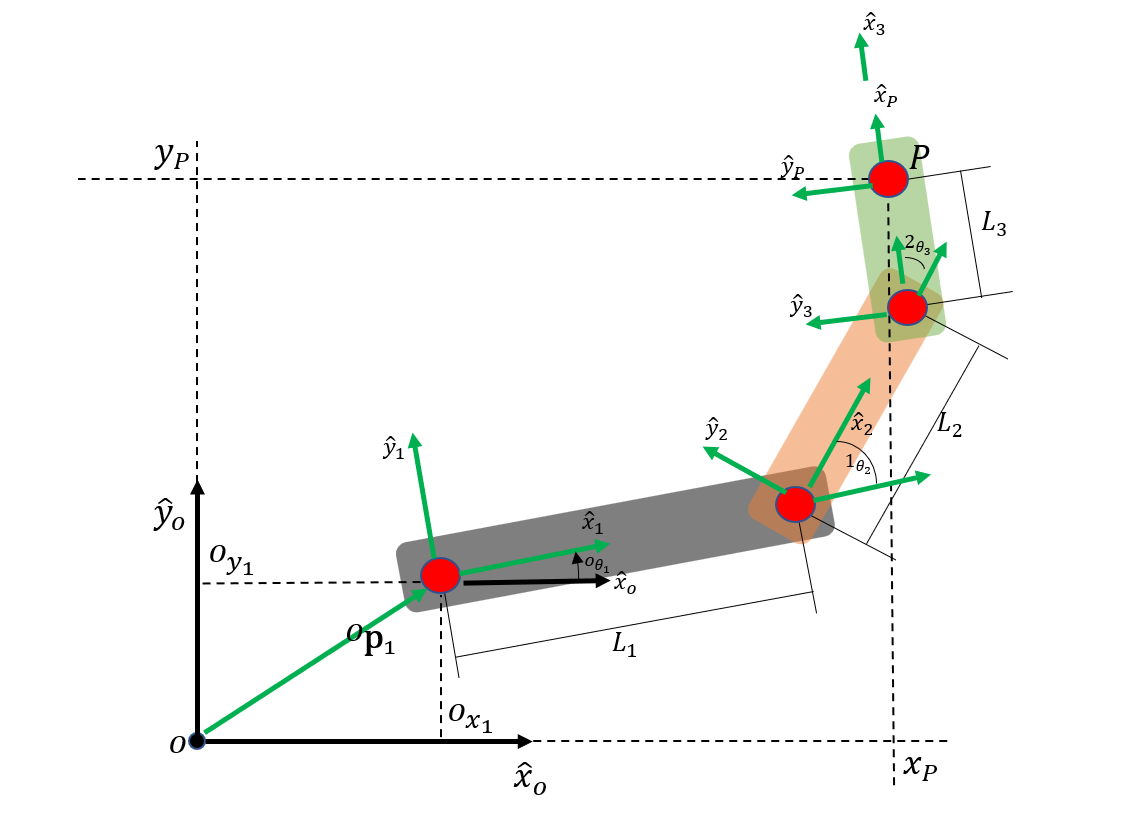

- ${}^1\mathbf{T}_{2}$: 

T_1_2 = Tij(L_1,0,0,0,0,theta_1_2)

$$R\_O\_1 = \left(\begin{array}{ccc} \cos\left(\theta_{O,1}\right) & -\sin\left(\theta_{O,1}\right) & 0\\ \sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

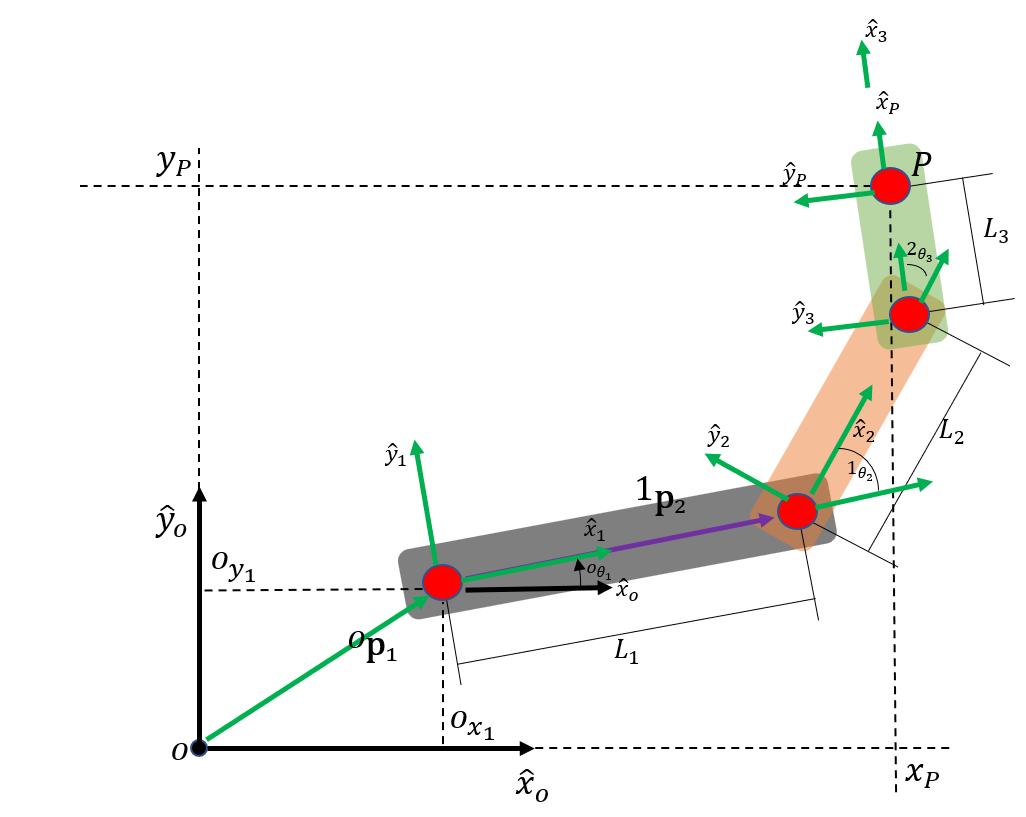

- ${}^2\mathbf{T}_{3
}$:

T_2_3 = Tij(L_2,0,0,0,0,theta_2_3)

$$R\_1\_O = \left(\begin{array}{ccc} \cos\left(\theta_{O,1}\right) & \sin\left(\theta_{O,1}\right) & 0\\ -\sin\left(\theta_{O,1}\right) & \cos\left(\theta_{O,1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

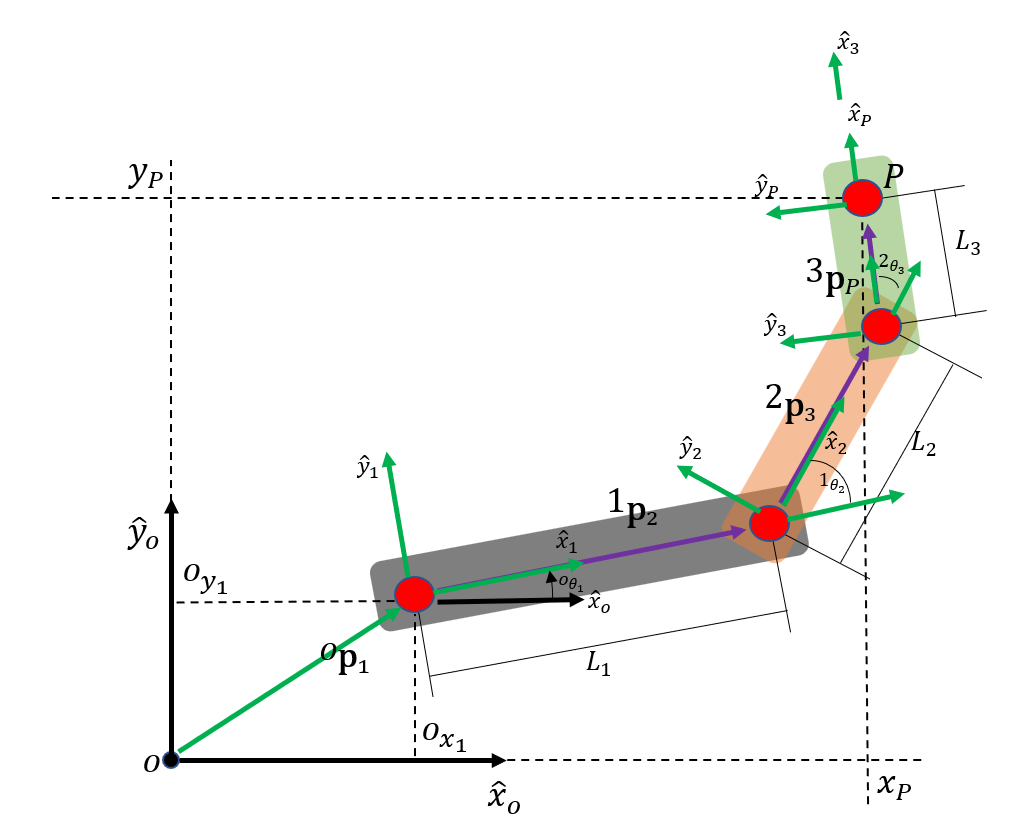

- ${}^3\mathbf{T}_{P}$:

T_3_P = Tij(L_3,0,0,0,0,0)

$$omega\_1\_1 = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{O,1} \end{array}\right)$$

Por lo tanto nuestra matriz general es la siguiente:

T_O_P = simplify(T_O_1*T_1_2*T_2_3*T_3_P)

$$v\_1\_1 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

Para el modelo cinemático de postura proponemos:

### 
$$\mathbf{F}={}^o\xi_{p} - {}^o\xi_{p}(q) = \mathbf{0}\Longrightarrow {}^o\xi_{p} = {}^o\xi_{p}(q)$$


Donde 


$$ {}^o\xi_{p}(q) = \pmatrix{{}^{o}\mathbf{p}_{P}\cr{}^{o}\mathbf{\theta}_{P}
}$$


Dado que obtivimos 

xi_O_P = [T_O_P(1,4);T_O_P(2,4);theta_O_1+theta_1_2+theta_2_3]

$$omega\_2\_2 = \omega_{2,2}$$

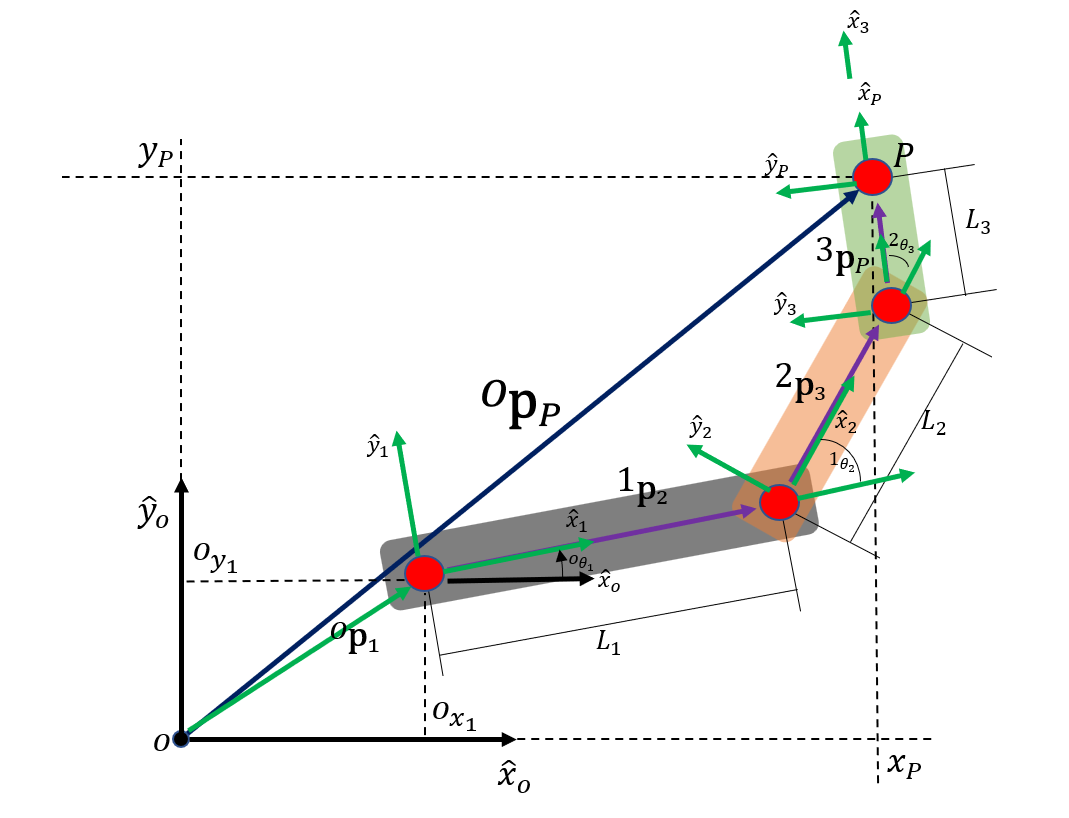

var = htrans(xi_O_P)

n_2_2 =      0
     0
     1


### Modelo inverso de postura

Dado que el modelo directo de postura no es una matriz cuadrada, para obtener su inversa se propone **pseudoinversa de Moore-Penrose (por izquierda debido a que la matriz contiene más filas que columnas)**:


$$A^+ ={\left(A^T A\right)}^{-1} A^T$$


Calculando matriz traspuesta:

AT = transpose(xi_O_P);

$$R\_1\_2 = \left(\begin{array}{ccc} \cos\left(\theta_{1,2}\right) & -\sin\left(\theta_{1,2}\right) & 0\\ \sin\left(\theta_{1,2}\right) & \cos\left(\theta_{1,2}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Realizando: ${\left(A^T A\right)}^{-1}$

Atemporal = (AT*xi_O_P)^(-1);

$$R\_2\_1 = \left(\begin{array}{ccc} \cos\left(\theta_{1,2}\right) & \sin\left(\theta_{1,2}\right) & 0\\ -\sin\left(\theta_{1,2}\right) & \cos\left(\theta_{1,2}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Realizando: ${\left(A^T A\right)}^{-1} A^T$

inv_xi_O_P = Atemporal*transpose(xi_O_P)

$$omega\_2\_2 = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1} \end{array}\right)$$

### Modelo cinemático directo de las velocidades

Partiendo del modelo de postura:

   
$${}^o\xi_{p} = {}^o\xi_{p}(q)$$
   

Aplicamos operador derivada total a ambos miembros del modelo:


$$\frac{d}{dt}{}^o\xi_{p} =\frac{d}{dt} {}^o\xi_{p}(q)$$
   

Desarrollando $\frac{d}{dt} {}^0\xi_{p}(q)$:

$\frac{d}{dt} {}^o\xi_{p}(q) = \frac{\partial}{\partial{}^o\theta_{1}}{}^o\xi_{p}(q) {}^o\dot\theta_{1}+\frac{\partial}{\partial{}^1\theta_{2}}{}^o\xi_{p}(q) {}^1\dot\theta_{2}+\frac{\partial}{\partial{}^2\theta_{3}}{}^o\xi_{p}(q) {}^2\dot\theta_{3}$...

... = $\left(\frac{\partial}{\partial{}\space^o\theta_{1}}{}^o\xi_{P}(q) \space\space\frac{\partial}{\partial\space{}^1\theta_{2}}{}^o\xi_{P}(q)\space\space\frac{\partial}{\partial\space{}^2\theta_{3}}{}^o\xi_{P}(q)\right)$ $\pmatrix{{}^{o}\dot{\theta}_{1} \cr {}^{1}\dot{\theta}_{2}\cr{}^{2}\dot{\theta}_{3}}$

De esta forma el modelo se puede representar de la siguiete forma:

### 
$${}^o\dot\xi_{P}=\mathbf{J}_{\theta}(q)\dot\mathbf{q}$$


Donde $\mathbf{J}_{\theta}(q)
$ es la siguiente matriz: 

syms J_theta


$$v\_2\_2 = \left(\begin{array}{c} L_{1}\,{\dot{\theta }}_{O,1}\,\sin\left(\theta_{1,2}\right)\\ L_{1}\,{\dot{\theta }}_{O,1}\,\cos\left(\theta_{1,2}\right)\\ 0 \end{array}\right)$$

J_theta 
J_theta = jacobian(xi_O_P,[theta_O_1, theta_1_2,theta_2_3])

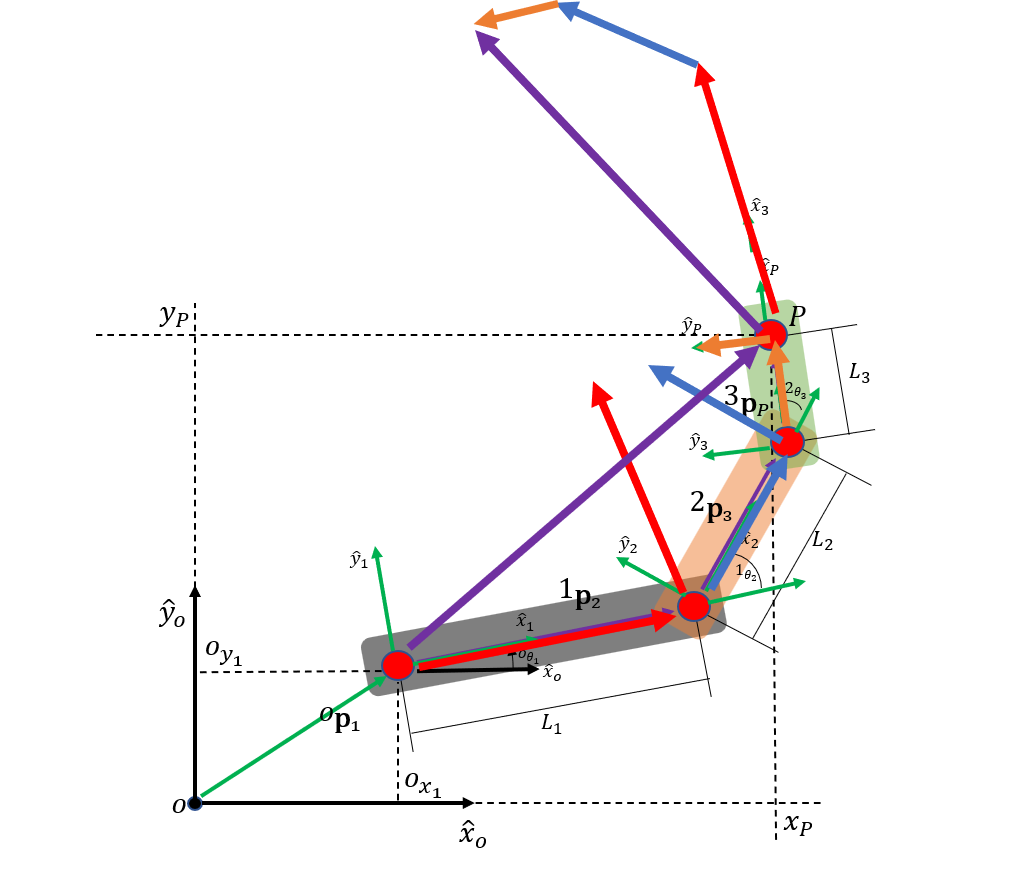

### Modelo cinemático inverso de las velocidades

Proponemos el siguiente modelo: 

### 
$$\dot\mathbf{q}={\mathbf{J}_{\theta}}^{-1}(q)\space{}^{o}\dot\xi_{P}$$


Dado que la matriz Jacobiana es una matriz cuadrada el modelo se simplifica.

Donde ${\mathbf{J}_{\theta}}^{-1}(q)$ es la siguiente matriz:

inv(J_theta)

$$omega\_3\_3 = \omega_{3,3}$$

Y donde ${}^{0}\dot\xi_{P}$ es el siguiente vector:


$$\pmatrix{{}^{o}\dot{x}_{P} \cr {}^{o}\dot{y}_{P}\cr{}^{o}\dot{\theta}_{P}}$$


### Modelo cinemático de las aceleraciones

Partiendo del modelo cinemático de velocidades (directo) :

   
$${}^o\dot\xi_{P}=\mathbf{J}_{\theta}(q)\dot\mathbf{q}$$


Aplicamos operador derivada total a ambos miembros del modelo:


$$\frac{d}{dt}{}^o\dot\xi_{p} =\frac{d}{dt}\left(\mathbf{J_{\theta}}(q)\dot\mathbf{q} \right)$$
   

        Desarrollando $\frac{d}{dt}\left(\mathbf{J_{\theta}}(q)\dot\mathbf{q} \right)$:

$\frac{d}{dt}\left(\mathbf{J_{\theta}}(q)\dot\mathbf{q} \right)= \dot\mathbf{J}_{\theta}(q,\dot{q})\dot\mathbf{q}+ \mathbf{J}_{\theta}(q)\ddot\mathbf{q}$...

Por lo tanto el modelo de aceleraciones directo es el siguiente:

### 
$${}^{o}\ddot\xi_{P}= \dot\mathbf{J}_{\theta}(q,\dot{q})\dot\mathbf{q}+ \mathbf{J}_{\theta}(q)\ddot\mathbf{q}$$


Donde:

-     
$$\ddot\mathbf{q}=\pmatrix{{}^{0}\ddot{\theta}_{1} \cr {}^{1}\ddot{\theta}_{2}\cr{}^{2}\ddot{\theta}_{3}}$$


- 
$$ \dot\mathbf{J}_{\theta}(q,\dot{q}) = \mathbf{H}_{\theta}(q,\dot{q}) $$


   Desarrollando  $ \mathbf{H}_{\theta}(q,\dot{q}) $ : 

syms theta_O_1 theta_1_2 theta_2_3 

n_3_3 =      0
     0
     1


$$R\_2\_3 = \left(\begin{array}{ccc} \cos\left(\theta_{2,3}\right) & -\sin\left(\theta_{2,3}\right) & 0\\ \sin\left(\theta_{2,3}\right) & \cos\left(\theta_{2,3}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

H_l_1 = hessian(xi_O_P(1,:),[theta_O_1, theta_1_2, theta_2_3])

$$R\_3\_2 = \left(\begin{array}{ccc} \cos\left(\theta_{2,3}\right) & \sin\left(\theta_{2,3}\right) & 0\\ -\sin\left(\theta_{2,3}\right) & \cos\left(\theta_{2,3}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

H_l_2 = hessian(xi_O_P(2,:),[theta_O_1, theta_1_2, theta_2_3])
H_l_3 = hessian(xi_O_P(3,:),[theta_O_1, theta_1_2, theta_2_3])
H_theta = [H_l_1(1,:);H_l_2(1,:);H_l_3(1,:)]

$$omega\_3\_3 = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1} \end{array}\right)$$

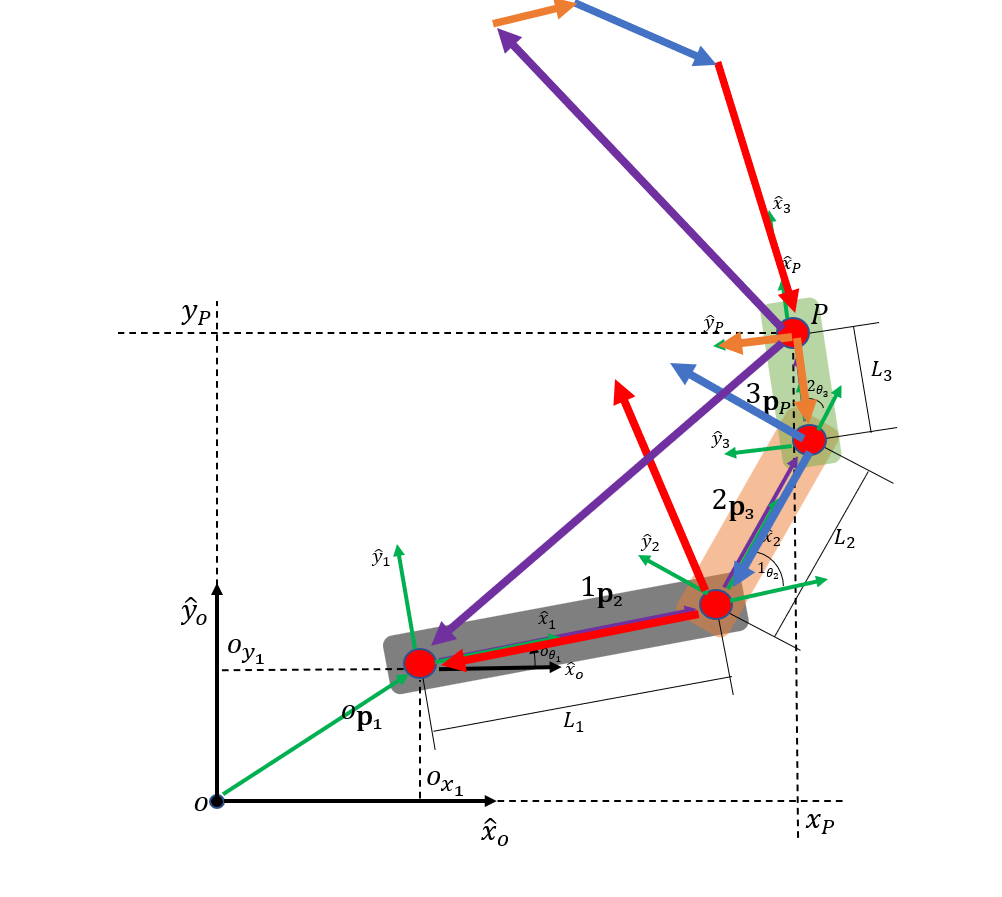

### Modelo cinemático inverso de las aceleraciones

Partiendo del modelo cinemático inverso de las velocidades, aplicamos derivada total a ambos miembros de la ecuación:


$$\frac{d}{dt}\dot\mathbf{q}=\frac{d}{dt}\left({\mathbf{J}_{\theta}}^{-1}(q)\space{}^{o}\dot\xi_{P}\right)$$


    Se aplica regla de la cadena en el miembro derecho


$$\frac{d}{dt}\left({\mathbf{J}_{\theta}}^{-1}(q)\space{}^{o}\dot\xi_{P}\right) = \frac{d}{dt}\left({\mathbf{J}_{\theta}}^{-1}(q)\right){}^{o}\dot\xi_{P}+{\mathbf{J}_{\theta}}^{-1}\frac{d}{dt}\left({}^{o} \dot\xi_{P}\right)=...
$$


            Desarrollando  $\frac{d}{dt}{\mathbf{J}_{\theta}}^{-1}(q)$ :


$$\frac{d}{dt}{\mathbf{J}_{\theta}}^{-1}(q) = \ddot{\mathbf{q}} = -\mathbf{J}_{\theta}^{-1}(q) \dot{\mathbf{J}}_{\theta}(q, \dot{q}) \mathbf{J}_{\theta}^{-1}(q) $$


Sustityuendo:


$$\ddot{\mathbf{q}} = -\mathbf{J}_{\theta}^{-1}(q) \dot{\mathbf{J}}_{\theta}(q, \dot{q}) \mathbf{J}_{\theta}^{-1}(q){}^o
\dot{\xi}_P + \mathbf{J}_{\theta}^{-1}(q) {}^o \ddot{\xi}_P$$


Simplificando con $\dot{\xi}_P = \mathbf{J}_{\theta}(q) \dot{\mathbf{q}}$ : 


$$\ddot{\mathbf{q}} = -\mathbf{J}_{\theta}^{-1}(q) \dot{\mathbf{J}}_{\theta}(q, \dot{q}) \dot{\mathbf{q}} + \mathbf{J}_{\theta}^{-1}(q){}^o \ddot{\xi}_P$$


### Modelo dinámico por ecuaciones de Eüler-Lagrange

Se emplearan las siguientes ecuaciones para el cálculo de la energía cinética:

### 
$$k_{i} = \frac{m_{i}}{2} \mathbf{v}_{C_{i}}^T \mathbf{v}_{C_{i}} + \frac{1}{2} \mathbf{\omega}_{C_{i}}^T \mathbf{I}_{C_{i}} \mathbf{\omega}_{C_{i}}


$$


syms x_1_C1 theta_dot_O_1


$$v\_3\_3 = \left(\begin{array}{c} \sin\left(\theta_{2,3}\right)\,\left(L_{2}\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1}\right)+L_{1}\,{\dot{\theta }}_{O,1}\,\cos\left(\theta_{1,2}\right)\right)+L_{1}\,{\dot{\theta }}_{O,1}\,\cos\left(\theta_{2,3}\right)\,\sin\left(\theta_{1,2}\right)\\ \cos\left(\theta_{2,3}\right)\,\left(L_{2}\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1}\right)+L_{1}\,{\dot{\theta }}_{O,1}\,\cos\left(\theta_{1,2}\right)\right)-L_{1}\,{\dot{\theta }}_{O,1}\,\sin\left(\theta_{1,2}\right)\,\sin\left(\theta_{2,3}\right)\\ 0 \end{array}\right)$$

v_C1_C1 = [0;x_1_C1*theta_dot_O_1;0]

v_O_C1 = [-x_1_C1*sin(theta_O_1)*theta_dot_O_1;x_1_C1*cos(theta_O_1)*theta_dot_O_1;0]
transpose(v_C1_C1)*v_C1_C1
simplify(transpose(v_O_C1)*v_O_C1)

## Cálculo de la posición de los centros de masa

Transformación ${}^{\mathrm{1}}{\mathbf{T}}_{\textrm{C1}}$

syms x_1_C1 x_2_C2 x_3_C3

n_P_P =      0
     0
     1


%nota: x_1_C1  = x_1/2

$$R\_3\_P = \left(\begin{array}{ccc} \cos\left(\theta_{2,3}\right) & -\sin\left(\theta_{2,3}\right) & 0\\ \sin\left(\theta_{2,3}\right) & \cos\left(\theta_{2,3}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

%nota: x_2_C2  = x_2/2

$$R\_P\_3 = \left(\begin{array}{ccc} \cos\left(\theta_{2,3}\right) & \sin\left(\theta_{2,3}\right) & 0\\ -\sin\left(\theta_{2,3}\right) & \cos\left(\theta_{2,3}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

%nota: x_3_C3  = x_3/2
T_1_C1 = Tij(x_1_C1,0,0,0,0,0)

Transformación ${}^0{\mathbf{T}}_{\textrm{C1}}$

T_O_C1 = T_O_1*T_1_C1

$$omega\_P\_P = \left(\begin{array}{c} 0\\ 0\\ {\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1} \end{array}\right)$$

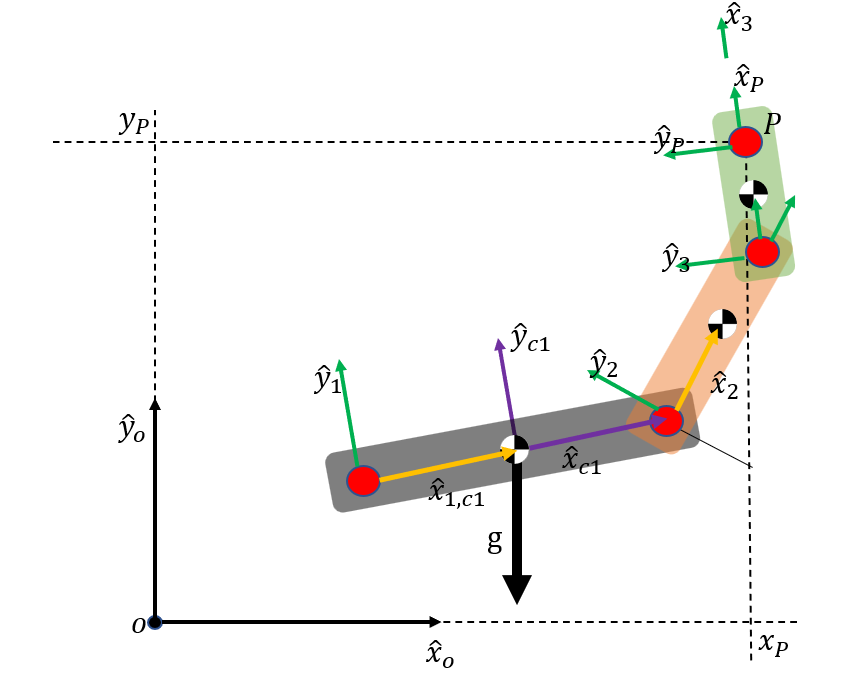

Transformación ${}^2{\mathbf{T}}_{\textrm{C2}}$

T_2_C2 = Tij(x_2_C2,0,0,0,0,0)

Transformación ${}^0{\mathbf{T}}_{\textrm{C2}}$

T_O_C2 = T_O_1*T_1_2*T_2_C2

$$v\_P\_P = \begin{array}{l} \left(\begin{array}{c} \cos\left(\theta_{2,3}\right)\,\sigma_{2}+\sin\left(\theta_{2,3}\right)\,\sigma_{1}\\ \cos\left(\theta_{2,3}\right)\,\sigma_{1}-\sin\left(\theta_{2,3}\right)\,\sigma_{2}\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{3}\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)+\cos\left(\theta_{2,3}\right)\,\left(L_{2}\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1}\right)+L_{1}\,{\dot{\theta }}_{O,1}\,\cos\left(\theta_{1,2}\right)\right)-L_{1}\,{\dot{\theta }}_{O,1}\,\sin\left(\theta_{1,2}\right)\,\sin\left(\theta_{2,3}\right)\\ \sigma_{2}=\sin\left(\theta_{2,3}\right)\,\left(L_{2}\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1}\right)+L_{1}\,{\dot{\theta }}_{O,1}\,\cos\left(\theta_{1,2}\right)\right)+L_{1}\,{\dot{\theta }}_{O,1}\,\cos\left(\theta_{2,3}\right)\,\sin\left(\theta_{1,2}\right) \end{array}$$

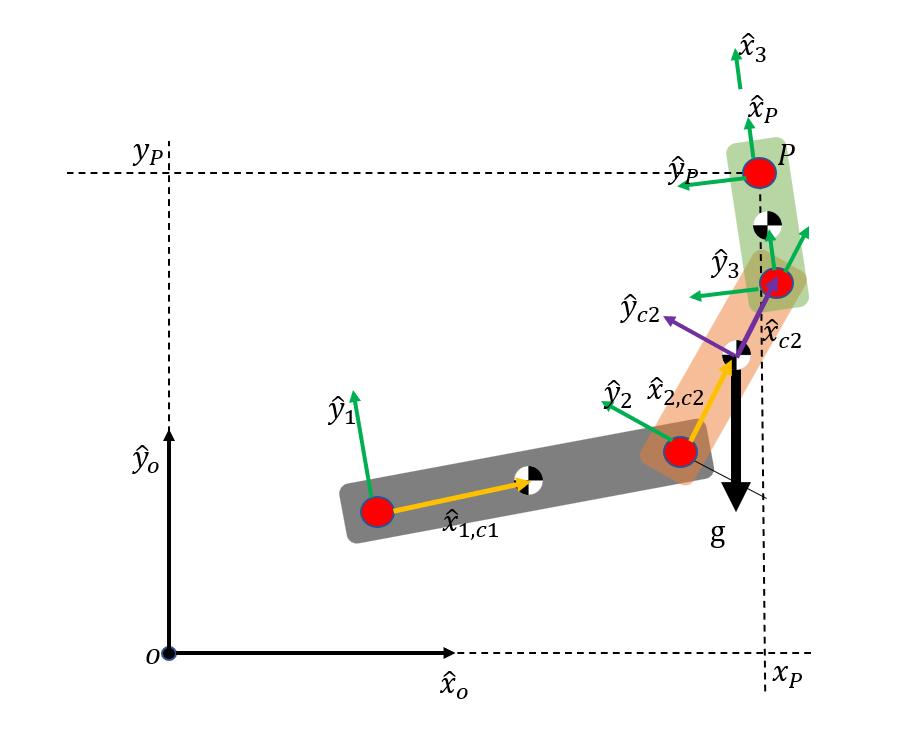

Transformación ${}^3{\mathbf{T}}_{\textrm{C3}}$

T_3_C3 = Tij(x_3_C3,0,0,0,0,0)

$$R\_O\_P = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{2} & -\sigma_{1}-\sin\left(\theta_{2,3}\right)\,\sigma_{3} & 0\\ \sigma_{1}+\sin\left(\theta_{2,3}\right)\,\sigma_{3} & \sigma_{2} & 0\\ 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{2,3}\right)\,\left(\cos\left(\theta_{2,3}\right)\,\left(\cos\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)+\cos\left(\theta_{O,1}\right)\,\sin\left(\theta_{1,2}\right)\right)+\sin\left(\theta_{2,3}\right)\,\left(\cos\left(\theta_{1,2}\right)\,\cos\left(\theta_{O,1}\right)-\sin\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)\right)\right)\\ \sigma_{2}=\cos\left(\theta_{2,3}\right)\,\sigma_{3}-\sin\left(\theta_{2,3}\right)\,\left(\cos\left(\theta_{2,3}\right)\,\left(\cos\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)+\cos\left(\theta_{O,1}\right)\,\sin\left(\theta_{1,2}\right)\right)+\sin\left(\theta_{2,3}\right)\,\left(\cos\left(\theta_{1,2}\right)\,\cos\left(\theta_{O,1}\right)-\sin\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)\right)\right)\\ \sigma_{3}=\cos\left(\theta_{2,3}\right)\,\left(\cos\left(\theta_{1,2}\right)\,\cos\left(\theta_{O,1}\right)-\sin\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)\right)-\sin\left(\theta_{2,3}\right)\,\left(\cos\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)+\cos\left(\theta_{O,1}\right)\,\sin\left(\theta_{1,2}\right)\right) \end{array}$$

Transformación ${}^0{\mathbf{T}}_{\textrm{C3}}$

T_O_C3 = simplify(T_O_1*T_1_2*T_2_3*T_3_C3)

$$v\_O\_P = \begin{array}{l} \left(\begin{array}{c} \sigma_{2}\,\sigma_{3}+\sigma_{1}\,\sigma_{4}\\ \sigma_{2}\,\sigma_{4}-\sigma_{1}\,\sigma_{3}\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{2,3}\right)\,\sigma_{5}-\sin\left(\theta_{2,3}\right)\,\sigma_{6}\\ \sigma_{2}=\cos\left(\theta_{2,3}\right)\,\sigma_{6}+\sin\left(\theta_{2,3}\right)\,\sigma_{5}\\ \sigma_{3}=\sin\left(\theta_{2,3}\right)\,\sigma_{8}-\cos\left(\theta_{2,3}\right)\,\sigma_{7}\\ \sigma_{4}=\cos\left(\theta_{2,3}\right)\,\sigma_{8}+\sin\left(\theta_{2,3}\right)\,\sigma_{7}\\ \sigma_{5}=\cos\left(\theta_{2,3}\right)\,\left(\cos\left(\theta_{1,2}\right)\,\cos\left(\theta_{O,1}\right)-\sin\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)\right)-\sin\left(\theta_{2,3}\right)\,\left(\cos\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)+\cos\left(\theta_{O,1}\right)\,\sin\left(\theta_{1,2}\right)\right)\\ \sigma_{6}=\cos\left(\theta_{2,3}\right)\,\left(\cos\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)+\cos\left(\theta_{O,1}\right)\,\sin\left(\theta_{1,2}\right)\right)+\sin\left(\theta_{2,3}\right)\,\left(\cos\left(\theta_{1,2}\right)\,\cos\left(\theta_{O,1}\right)-\sin\left(\theta_{1,2}\right)\,\sin\left(\theta_{O,1}\right)\right)\\ \sigma_{7}=L_{3}\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{2,3}+{\dot{\theta }}_{O,1}\right)+\cos\left(\theta_{2,3}\right)\,\left(L_{2}\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1}\right)+L_{1}\,{\dot{\theta }}_{O,1}\,\cos\left(\theta_{1,2}\right)\right)-L_{1}\,{\dot{\theta }}_{O,1}\,\sin\left(\theta_{1,2}\right)\,\sin\left(\theta_{2,3}\right)\\ \sigma_{8}=\sin\left(\theta_{2,3}\right)\,\left(L_{2}\,\left({\dot{\theta }}_{1,2}+{\dot{\theta }}_{O,1}\right)+L_{1}\,{\dot{\theta }}_{O,1}\,\cos\left(\theta_{1,2}\right)\right)+L_{1}\,{\dot{\theta }}_{O,1}\,\cos\left(\theta_{2,3}\right)\,\sin\left(\theta_{1,2}\right) \end{array}$$

Por lo tanto, los vectores de posición de los centros de masa:

%Vectores de posición
p_O_C1 = [T_O_C1(1,4);T_O_C1(2,4);T_O_C1(3,4)]
p_O_C2 = simplify([T_O_C2(1,4);T_O_C2(2,4);T_O_C2(3,4)])

p_O_C3 = simplify([T_O_C3(1,4);T_O_C3(2,4);T_O_C3(3,4)])

## Cálculo de las velocidades

Cálculo de las velocidades lineales del sistema ${}^0{\mathbf{v}}_{\textrm{Ci}}=\frac{\mathrm{d}}{\textrm{dt}}{}^0{\mathbf{p}}_{\textrm{Ci}}=\frac{\mathrm{d}}{\mathrm{d}\theta_{O,1} }{}^0{\mathbf{p}}_{\textrm{Ci}}+\frac{\mathrm{d}}{\mathrm{d}\theta_{1,2} }{}^0{\mathbf{p}}_{\textrm{Ci}}+\frac{\mathrm{d}}{\mathrm{d}\theta_{2,3} }{}^0{\mathbf{p}}_{\textrm{Ci}}$:

syms theta_dot_O_1 theta_dot_1_2 theta_dot_2_3

v_O_C1 = simplify(diff(p_O_C1,theta_O_1)*theta_dot_O_1+diff(p_O_C1,theta_1_2)*theta_dot_1_2+diff(p_O_C1,theta_2_3)*theta_dot_2_3)
v_O_C2 = simplify(diff(p_O_C2,theta_O_1)*theta_dot_O_1+diff(p_O_C2,theta_1_2)*theta_dot_1_2+diff(p_O_C2,theta_2_3)*theta_dot_2_3)
v_O_C3 = simplify(diff(p_O_C3,theta_O_1)*theta_dot_O_1+diff(p_O_C3,theta_1_2)*theta_dot_1_2+diff(p_O_C3,theta_2_3)*theta_dot_2_3)

Cálculo de la velocidades angulares del sistema

Utilizando la fórmula


$$${}^{i+1}{\omega }_{i+1}={}^{i+1}{\mathbf{R}}_i{}^i{\omega }_i+{}^{i+1}{\hat{\mathbf{z}} }_{i+1}{\dot{\theta} }_{i+1}$$$


y considerando que


$${}^1{\mathbf{R}}_0={{}^0{\mathbf{R}}_1}^{-1} ={{}^0{\mathbf{R}}_1}^T$$


Propagación de velocidades angulares del primer cuerpo:

syms omega_1_1 omega_2_2 omega_3_3
%Propagación para el primer cuerpo
omega_1_1

Al no haber velocidad angular en el punto 0:

omega_O_O = [0;0;0]

Eje de rotación

n_1_1 = [0;0;1]
R_O_1 = [T_O_1(1,1),T_O_1(1,2),T_O_1(1,3);T_O_1(2,1),T_O_1(2,2),T_O_1(2,3);T_O_1(3,1),T_O_1(3,2),T_O_1(3,3)]
R_1_O = transpose(R_O_1)

%Ecuación de propagación
omega_1_1 = R_1_O*omega_O_O+n_1_1*theta_dot_O_1

## **Propagación de velocidades lineales entre el sistema {0} al sistema {1}**

Proponiendo: 


$${}^{1}\mathbf{v}_1 = {}^{o}\mathbf{R}_1 ({}^{o}\mathbf{v}_o+{}^{o}\mathbf{\omega}_o\times{}^{o}\mathbf{p}_1)$$


v_1_1 = R_1_O*([0;0;0]+cross([0;0;0],[x_O_1;y_O_1;0]))

## 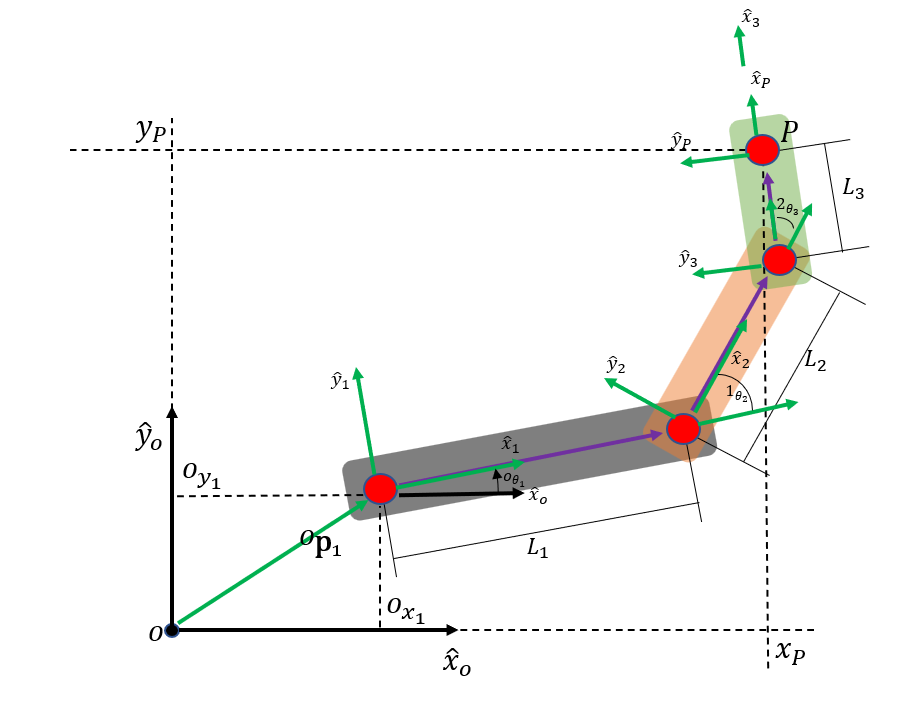

## **Propagación de velocidades angulares del segundo cuerpo:**

%Propagación para el segundo cuerpo
omega_2_2
n_2_2 = [0;0;1]
R_1_2 = [T_1_2(1,1),T_1_2(1,2),T_1_2(1,3);T_1_2(2,1),T_1_2(2,2),T_1_2(2,3);T_1_2(3,1),T_1_2(3,2),T_1_2(3,3)]
R_2_1 = transpose(R_1_2)
%Ecuación de propagación
omega_2_2 = R_2_1*omega_1_1+n_2_2*theta_dot_1_2

## **Propagación de velocidades lineales entre el sistema {1} al sistema {2}**

Proponiendo: 


$${}^{2}\mathbf{v}_2 = {}^{2}\mathbf{R}_1 ({}^{1}\mathbf{v}_+{}^{1}\mathbf{\omega}_1\times{}^{1}\mathbf{p}_2)$$


syms L1 
v_2_2 = R_2_1*(v_1_1+cross(omega_1_1,[L1;0;0]))

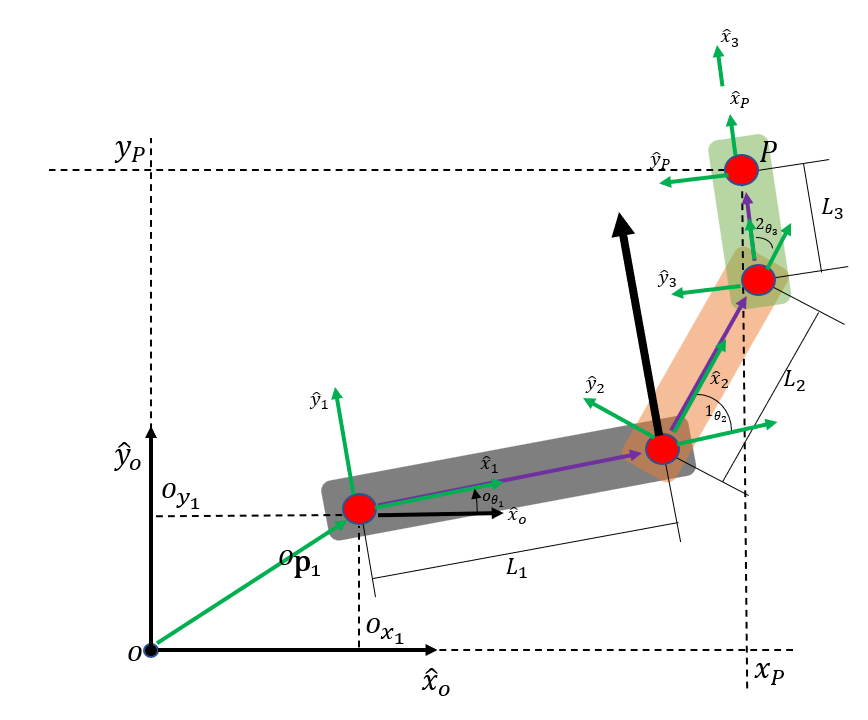

## **Propagación de velocidades angulares del tercer cuerpo:**

%Propagación para el tercer cuerpo
omega_3_3
n_3_3 = [0;0;1]
R_2_3 = [T_2_3(1,1),T_2_3(1,2),T_2_3(1,3);T_2_3(2,1),T_2_3(2,2),T_2_3(2,3);T_2_3(3,1),T_2_3(3,2),T_2_3(3,3)]
R_3_2 = transpose(R_2_3)

%Ecuación de propagación
omega_3_3 = R_3_2*omega_2_2+n_3_3*theta_dot_2_3

## **Propagación de velocidades lineales entre el sistema {2} al sistema {3}**

Proponiendo: 


$${}^{3}\mathbf{v}_3 = {}^{3}\mathbf{R}_2 ({}^{2}\mathbf{v}_2+{}^{2}\mathbf{\omega}_2\times{}^{2}\mathbf{p}_3)$$


syms L2 
v_3_3 = R_3_2*(v_2_2+cross(omega_2_2,[L2;0;0]))

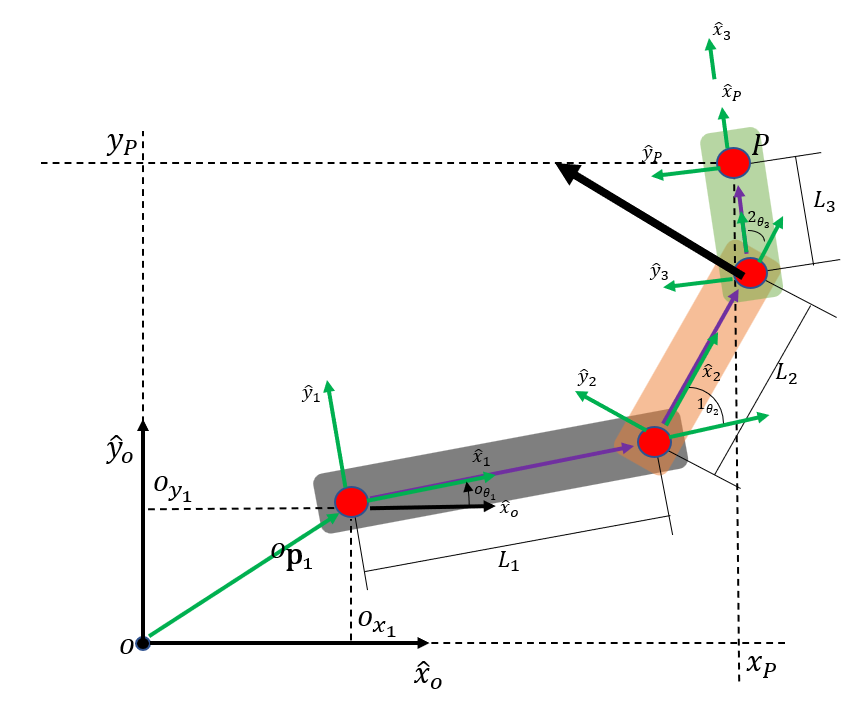

## **Propagación de velocidades angulares EN EL PUNTO P:**

%Propagación en el punto P

n_P_P = [0;0;1]
R_3_P = [T_2_3(1,1),T_2_3(1,2),T_2_3(1,3);T_2_3(2,1),T_2_3(2,2),T_2_3(2,3);T_2_3(3,1),T_2_3(3,2),T_2_3(3,3)]
R_P_3 = transpose(R_3_P)

%Ecuación de propagación
omega_P_P = R_P_3*omega_3_3+n_P_P*0

## **Propagación de velocidades lineales entre el sistema {3} al sistema {P}**

Proponiendo: 


$${}^{P}\mathbf{v}_P = {}^{P}\mathbf{R}_3 ({}^{3}\mathbf{v}_3+{}^{3}\mathbf{\omega}_3\times{}^{3}\mathbf{p}_P)$$


syms L3 
v_P_P = R_P_3*(v_3_3+cross(omega_3_3,[L3;0;0]))

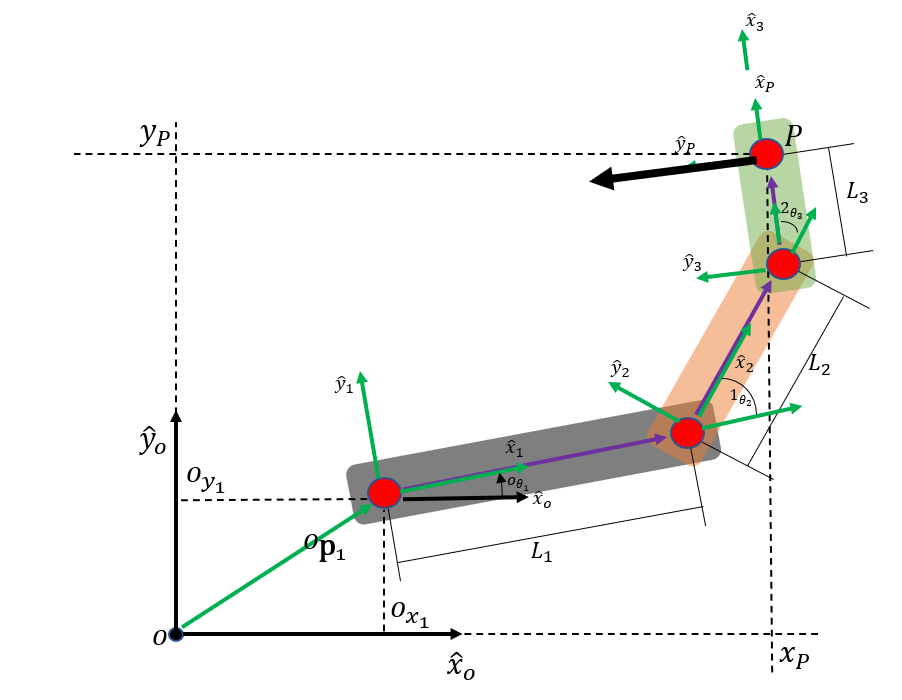

## **Propagación de velocidades lineales entre el sistema {P} al sistema {0}**

Proponemos: 


$${}^{0}\mathbf{v}_{P}={}^{o}\mathbf{R}_P\space{}^{P}\mathbf{v}_{P}$$


Donde

- 
$${}^{o}\mathbf{R}_P = {}^{o}\mathbf{R}_1\space {}^{1}\mathbf{R}_2  \space {}^{2}\mathbf{R}_3 \space {}^{3}\mathbf{R}_P   $$


R_O_P = R_O_1*R_1_2*R_2_3*R_3_P

Resolviendo ${}^{0}\mathbf{v}_{P}={}^{o}\mathbf{R}_P\space{}^{P}\mathbf{v}_{P}
$ : 

v_O_P = R_O_P*v_P_P

## Defición de los elementos de inercia 

Vector de gravedad en el eje en el que se aplica

syms g I_xx1 I_yy1 I_zz1 I_xx2 I_yy2 I_zz2 I_xx3 I_yy3 I_zz3
%vector de gravedad

g_v = [0;-g;0]

Matrices de inercia independientes de cada cuerpo:

I_C1 = [I_xx1,0,0;0,I_yy1,0;0,0,I_zz1]
I_C2 = [I_xx2,0,0;0,I_yy2,0;0,0,I_zz2]
I_C3 = [I_xx3,0,0;0,I_yy3,0;0,0,I_zz3]

**Cáculo del Lagrangeano**

La energía cinética es una constante que se calcula mediante la fórmula


$$k=\frac{1}{2}m_1 {\mathbf{v}}_{\textrm{C1}}^T {\mathbf{v}}_{\textrm{C1}} +\frac{1}{2}{{}^1{\omega }_1}^T {\mathrm{I}}_{\textrm{C1}} {}^1{\omega }_1$$


Energía cinética del primer cuerpo:

syms m_1 m_2 m_3
%energía cinética de cada uno de los cuerpos

k_1 = simplify((m_1/2)*transpose(v_O_C1)*v_O_C1+(1/2)*transpose(omega_1_1)*I_C1*omega_1_1)

Energía cinética del segundo cuerpo:

k_2 = simplify((m_2/2)*transpose(v_O_C2)*v_O_C2+(1/2)*transpose(omega_2_2)*I_C2*omega_2_2)

Energía cinética del tercer cuerpo:

k_3 = simplify((m_3/2)*transpose(v_O_C3)*v_O_C3+(1/2)*transpose(omega_3_3)*I_C3*omega_3_3)

También es necesaria la energía potencia que se obtiene mediante


$$u_1 =-m_1 {\mathbf{g}}^T {}^0{\mathbf{p}}_{\textrm{C1}}$$


Energía potencial del primer cuerpo:

% Cáclulo de la energía potencial de cada cuerpo

u_1 = -m_1*transpose(p_O_C1)*g_v

Energía potencial del segundo cuerpo:

u_2 = -m_2*transpose(p_O_C2)*g_v

Energía potencial del tercer cuerpo:

u_3 = -m_3*transpose(p_O_C3)*g_v

Cálculo del Lagrangeano

El Lagrangeano se define como


$$\Gamma =\left(k_1 +k_2 +k_3 \right)-\left(u_1 +u_2 +u_3 \right)$$


La = (k_1+k_2+k_3)-(u_1+u_2+u_3)

## Cálculo de los pares

La ecuación de par se define como


$$\tau_i =\frac{d}{\textrm{dt}}\left(\frac{\delta }{\delta {\dot{q} }_i }\Gamma \right)-\frac{\delta }{\delta q_i }\Gamma$$


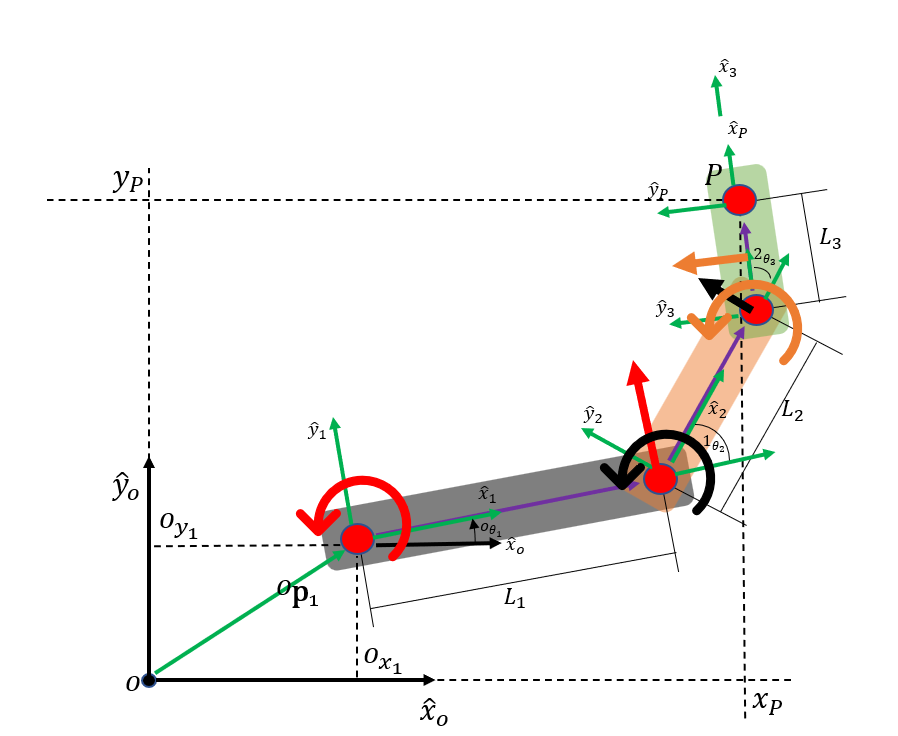

En la que se tiene que obtener la derivada parcial del Lagrangiano respecto a la velocidad de cada junta y posteriormente aplicar la regla de la cadena respecto a cada variable que resulte de la operación

Derivada parcial del Lagrangiano respecto a la velocidad del cuerpo 1:

syms theta_ddot_O_1 theta_ddot_1_2 theta_ddot_2_3

D_theta1 = diff(La,theta_dot_O_1)

Par del cuerpo 1 aplicando regla de la cadena y restando la derivada parcial respecto a theta:

% Cálculo de relación

tao_1 = diff(D_theta1,theta_O_1)*theta_dot_O_1 + diff(D_theta1,theta_1_2)*theta_dot_1_2 + diff(D_theta1,theta_2_3)*theta_dot_2_3 + diff(D_theta1,theta_dot_O_1)*theta_ddot_O_1+ diff(D_theta1,theta_dot_1_2)*theta_ddot_1_2+ diff(D_theta1,theta_dot_2_3)*theta_ddot_2_3-diff(La,theta_O_1)

Derivada parcial del Lagrangiano respecto a la velocidad del cuerpo 2:

D_theta2 = diff(La,theta_dot_1_2)

Par del cuerpo 2 aplicando regla de la cadena y restando la derivada parcial respecto a theta:

tao_2 = diff(D_theta2,theta_O_1)*theta_dot_O_1 + diff(D_theta2,theta_1_2)*theta_dot_1_2 + diff(D_theta2,theta_2_3)*theta_dot_2_3 + diff(D_theta2,theta_dot_O_1)*theta_ddot_O_1+ diff(D_theta2,theta_dot_1_2)*theta_ddot_1_2+ diff(D_theta2,theta_dot_2_3)*theta_ddot_2_3-diff(La,theta_1_2)

Derivada parcial del Lagrangiano respecto a la velocidad del cuerpo 3:

D_theta3 = diff(La,theta_dot_2_3)

Par del cuerpo 3 aplicando regla de la cadena y restando la derivada parcial respecto a theta:

tao_3 = diff(D_theta3,theta_O_1)*theta_dot_O_1 + diff(D_theta3,theta_1_2)*theta_dot_1_2 + diff(D_theta3,theta_2_3)*theta_dot_2_3 + diff(D_theta3,theta_dot_O_1)*theta_ddot_O_1+ diff(D_theta3,theta_dot_1_2)*theta_ddot_1_2+ diff(D_theta3,theta_dot_2_3)*theta_ddot_2_3-diff(La,theta_2_3)

Vector de par resultante. El par aplicando en cada junta 

tao = [tao_1;tao_2;tao_3]

Matrices de incercia que experimenta cada junta debido a la aceleración

% Cálculo de la matriz de inercia

M1 = subs(tao,[theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,g],[1,0,0,0,0,0,0])
M2 = subs(tao,[theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,g],[0,1,0,0,0,0,0])
M3 = subs(tao,[theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,g],[0,0,1,0,0,0,0])

Matriz de inercias debido al cambio en la velocidad de cada junta:

M_theta = collect([M1 M2 M3],[m_1,m_2,m_3])

Cálculo del vector de pares por efecto Coriolis. Par que experimenta cada junta debido a la velocidad

V_theta = subs(tao,[theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,g],[0,0,0,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,0])

Cálculo del vector de pares por efecto de la gravedad. Par que experimenta cada junta debido a la gravedad

G_theta = subs(tao,[theta_ddot_O_1,theta_ddot_1_2,theta_ddot_2_3,theta_dot_O_1,theta_dot_1_2,theta_dot_2_3,g],[0,0,0,0,0,0,g])

Obteniendo así el modelo Dinámico en el que:


$$\tau_{\theta } =\mathbf{M}\left(\theta \right)\ddot{\theta} +\mathbf{V}\left(\theta ,\dot{\theta} \right)+\mathbf{G}\left(\theta \right)$$


## Cálculo del modelo dinámico inverso

Para obtener el modelo dinámico inverso partimos de la siguiente ecuación 


$$\ddot{\theta} = M^{-1}(\theta) \left( \tau - V(\theta, \dot{\theta}) - G(\theta)\right)$$


Obtenemos la inversa de la matriz de inercia 

M_inv = simplify(inv(M_theta))

Por último caculamos el modelo desdeado

theta_ddot =M_inv*(tao-V_theta-G_theta)
theta_ddot_s =simplify(M_inv*(tao-V_theta-G_theta))

#### Conclusiones

Se lograron obtener los diversos modelos matemáticos planteados al inicio. El razonamiento fue el adecuado y, sin duda alguna, el uso del software ayudó con la simplificación de las ecuaciones.

Se realizaron investigaciones para hallar la forma de obtener los modelos inversos de las ecuaciones. Al tratarse de operaciones con matrices, el despeje de estas presenta un comportamiento distinto al de los escalares, sumado al hecho de que las matrices pueden o no ser cuadradas.

Un ejemplo claro, utilizado en el examen, fue la obtención del modelo inverso de la postura del robot. Debido a que el modelo directo de postura no es una matriz cuadrada, se tuvo que utilizar la ecuación pseudoinversa de Moore-Penrose para obtener el resultado deseado.

Otro punto clave para la adecuada obtención de resultados fue nombrar a las variables de forma clara y ordenada. El archivo contiene más de sesenta variables; por ello, fue necesario identificar con precisión qué representa cada una. Además, muchas de estas variables se reutilizaban en distintas ocasiones, lo cual facilitó la programación de las ecuaciones posteriores.

Si bien se trató de un modelo básico, en mi opinión fue una excelente manera de comenzar a interpretar los principios de movilidad de un robot genérico. Un análisis profundo fue necesario para aprender a leer las ecuaciones y, con base en ellas, llegar a un modelo final en cada sección.